% List of battery cell identifiers
Battery_list = {'cell03_1',    'cell04',    'cell05',  'cell06',  ...
                'cell07',      'cell08',    'cell09',  'cell10',  ...
                'cell11_1',    'cell11_2',  'cell12',  'cell13',  ...
                'cell14',      'cell15',    'cell16'};

% Corresponding nominal capacities
NormCap_list = [4.2566, 4.3639, 4.4623, 4.3373, ...
                4.3486, 4.4997, 4.3737, 4.5599, ...
                3.9674, 4.2512, 4.6559, 4.3722, ...
                4.6667, 4.5953, 4.6188];

% File name and path for the retention data Excel file
fileName = 'CellRetention.xlsx';
filePath = fullfile('dataset', fileName);
sheets = sheetnames(filePath);

% Define custom colors (RGB triplets)

Gray = [0.75 0.75 0.75];
Lime = [0.2 0.8 0.2];
Gold = [1 0.8 0];
Chocolate = [0.8 0.4 0.1];
Steel = [0.3 0.5 0.7];
Salmon = [1 0.5 0.4];
Voilet = [0.9 0.5 0.9];

% Select a specific battery by index
fileID = 11;

% Read data from the selected sheet, skipping the header row
Data = readmatrix(filePath,'Sheet',Battery_list{fileID});
Data(1,:) = [];

cycle = Data(:,1);
capacity = Data(:,2)/100;

% Use data from cycle 10 for fitting (remove early cycles)
cycle_fit = Data(10:end,1);
capacity_fit = Data(10:end,2)/100;
OutliersRemoval(capacity_fit,10,1);
% capacity = smooth(capacity);

% Define model functions:

% Double exponential decay
DoubleExp = @(p,k) p(1) * exp(p(2) * k) + p(3) * exp(p(4) * k);
% Double power law degradation model
DoublePower = @(p,k) 1 - p(1) * k.^p(2) - p(3) * k.^p(4);
% Bacon-Watts model: piecewise linear fitting
Bacon_Watts = @(p,k) p(1)+p(2)*(k-p(4))+p(3)*(k-p(4)).*tanh((k-p(4))/1e-5);
% Double Bacon-Watts model: two breakpoints piecewise linear fitting
Double_Bacon_Watts = @(p,k) p(1)+p(2)*(k-p(4))+p(3)*(k-p(4)).*tanh((k-p(4))/1e-5)+p(5)*(k-p(6)).*tanh((k-p(6))/1e-5);

% Prepare data for fitting (Curve Fitting Toolbox format)
[xData, yData] = prepareCurveData(cycle_fit,capacity_fit);

% ------------------- Single Bacon-Watts model fit -------------------
% Define fit type: a + b*(x-d) + c*(x-d)*tanh((x-d)/0.1)
ft = fittype( 'a+b*(x-d)+c*(x-d)*tanh((x-d)/0.1)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf 0];
opts.Upper = [Inf 0 0 Inf];
opts.StartPoint = [1 0 0 100];

[fitresult, gof] = fit(xData,yData,ft,opts);

% Extract fitted parameters and compute fitted curve
Exp_para = [fitresult.a;fitresult.b;fitresult.c;fitresult.d];
fitExp = Bacon_Watts(Exp_para,cycle);
% Knee point (first breakpoint) from single model
KneePoint = round(fitresult.d);

[xData, yData] = prepareCurveData(cycle_fit,capacity_fit);

% ------------------- Double Bacon-Watts model fit -------------------
% Two smooth breakpoints: a + b*(x-d) + c*(x-d)*tanh((x-d)/0.1) + e*(x-f)*tanh((x-f)/1e-5)
ft = fittype( 'a+b*(x-d)+c*(x-d)*tanh((x-d)/0.1)+e*(x-f)*tanh((x-f)/1e-5)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [0 -Inf -Inf 0 -Inf 0];
opts.Upper = [Inf 0 0 Inf 0 Inf];
opts.StartPoint = [1 0 0 100 0 150];

[fitresult, gof] = fit(xData,yData,ft,opts);

% Extract fitted parameters and compute fitted curve
Exp_para = [fitresult.a;fitresult.b;fitresult.c;fitresult.d;fitresult.e;fitresult.f];
fitExp_Double = Double_Bacon_Watts(Exp_para,cycle);
% Knee onset and Knee point (two breakpoints) from double model
KneeOnset = round(fitresult.d);
KneePoint_plus = round(fitresult.f);

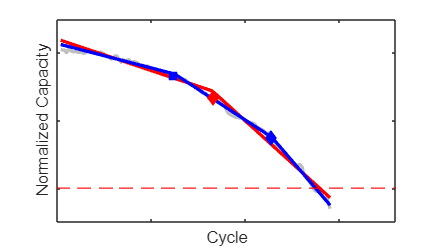

% ------------------- Plotting -------------------
figure
set(figure,'Position', [680,250,350,200]);
hold on;box on;
plot(cycle,capacity,'Color',Gray,'LineWidth',2,'DisplayName','Capacity')
plot(cycle,fitExp,'r-','LineWidth',2,'DisplayName','Bacon-Watts Model')
plot(cycle,fitExp_Double,'b-','LineWidth',2,'DisplayName','Double Bacon-Watts Model')

scatter(KneePoint,capacity(KneePoint),'r','filled','diamond','MarkerEdgeColor','flat');
scatter(KneeOnset,capacity(KneeOnset),'b','filled','square','MarkerEdgeColor','flat');
scatter(KneePoint_plus,capacity(KneePoint_plus),'b','filled','diamond','MarkerEdgeColor','flat');
yline(0.8,'Color','r','LineWidth',1,'LineStyle','--');
xlabel('Cycle');
ylabel('Normalized Capacity')
xlim([0 180]);
ylim([0.75 1.05])
set(gca, 'XTickLabel', []);
set(gca, 'YTickLabel', []);